# **DEMO_01:**   **Kinematic** analysis of Slider crank mechanism

`Bradley Horton : 25-Feb-2022, bhorton@mathworks.com`

Consider the slider crank mechanism shown in **Figure 1** below. 

**TOLD:**

- Crank AB rotates with a CONSTANT angular velocity of $\omega_{\textrm{AB}} =150\;\frac{\textrm{rad}}{\sec }$

**FIND:**

- The velocity of point P when $\theta =30\;\textrm{degrees}$

**Figure 1**:  the system to be analysed

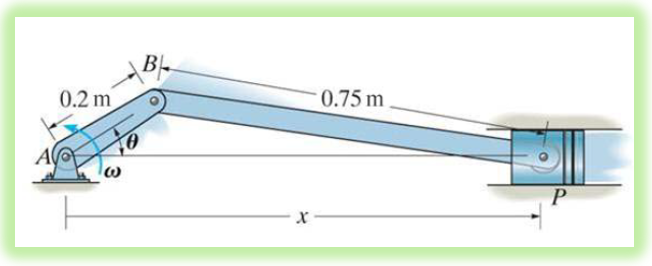

## Geometry relationship:

## 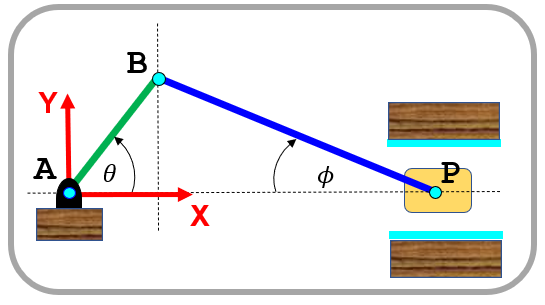

From the mechanism's geometry we see that:

- $L_{\textrm{AB}} \ldotp \sin \left(\theta \left(t\right)\right)\;\;=\;\;L_{\textrm{BP}} \ldotp \sin \left(\phi \left(t\right)\right)$    ................    **EQ_1**

## The Velocity Analysis:

Consider the diagram below

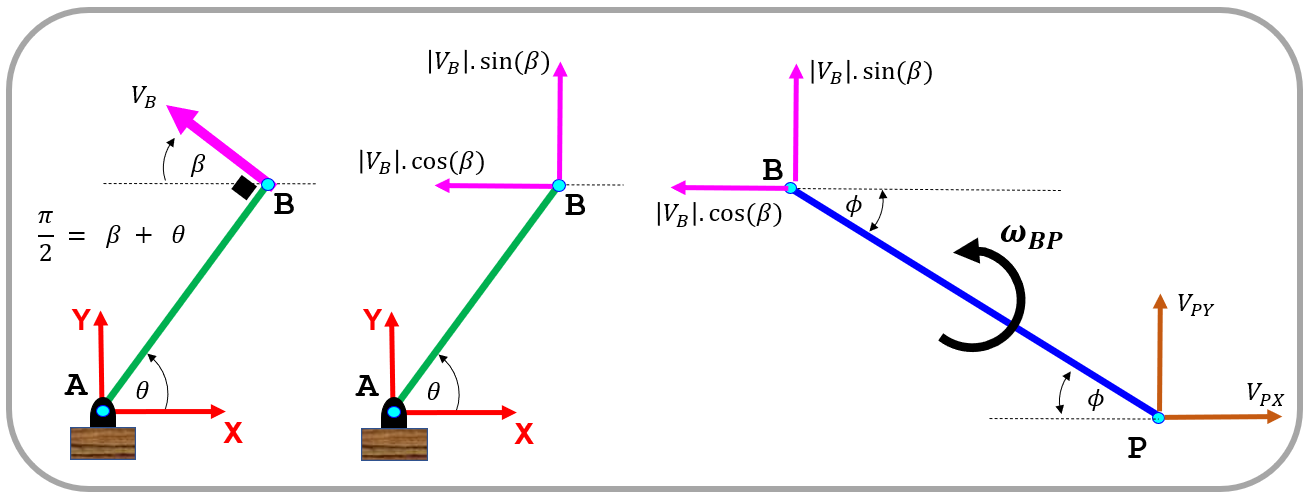

Consider **Link **$\textrm{AB}$:   the velocity of point $B$ is

- $v_B \;\;={\tilde{\omega} }_{\textrm{AB}} \;\;\times r_{B|A} \;\;=\;\left|\left\lbrack \begin{array}{ccc}
i & j & k\\
0 & 0 & \omega_{\textrm{AB}} \\
L_{\textrm{AB}} \ldotp \cos \left(\theta \right) & L_{\textrm{AB}} \ldotp \sin \left(\theta \right) & 0
\end{array}\right\rbrack \right|\;=\left\lbrack \begin{array}{c}
-\omega_{\textrm{AB}} \ldotp L_{\textrm{AB}} \ldotp \sin \left(\theta \right)\\
\omega_{\textrm{AB}} \ldotp L_{\textrm{AB}} \ldotp \cos \left(\theta \right)\\
0
\end{array}\right\rbrack$    ................    **EQ_2**

Consider **Link **$\textrm{BP}$:   the velocity of point $P$ is

- 
$$v_P \;\;=\;v_B \;\;\;\;+\;\;\;\;{\tilde{\omega} }_{\textrm{BP}} \times r_{P\left|B\right.} \;\;\;\;=\;\;\left\lbrack \begin{array}{c}
v_{\textrm{BX}} \\
v_{\textrm{BY}} 
\end{array}\right\rbrack \;\;\;+\;\;\;\left|\left\lbrack \begin{array}{ccc}
i & j & k\\
0 & 0 & \omega_{\textrm{BP}} \\
L_{\textrm{BP}} \ldotp \cos \left(\phi \right) & {-L}_{\textrm{BP}} \ldotp \sin \left(\phi \right) & 0
\end{array}\right\rbrack \right|\;\;=\;\;\left\lbrack \begin{array}{c}
v_{\textrm{BX}} \;\;+\;L_{\textrm{BP}} \ldotp \sin \left(\phi \right)\ldotp \omega_{\textrm{BP}} \\
v_{\textrm{BY}} +\;L_{\textrm{BP}} \ldotp \cos \left(\phi \right)\ldotp \omega_{\textrm{BP}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
v_{\textrm{PX}} \\
v_{\textrm{PY}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
v_{\textrm{PX}} \\
0
\end{array}\right\rbrack$$


Since $v_{\textrm{PY}} =0$ we can write:

- 
$${0\;\;\;=\;\;v}_{\textrm{BY}} +\;L_{\textrm{BP}} \ldotp \cos \left(\phi \right)\ldotp \omega_{\textrm{BP}}$$
 

- $\omega_{\textrm{BP}} \;\;=\;\;\frac{{-v}_{\textrm{BY}} }{L_{\textrm{BP}} \ldotp \cos \left(\phi \right)}$                         ................    **EQ_3**

And we can now solve for $v_{\textrm{BX}}$

- ${v_{\textrm{PX}} \;\;\;=\;\;\;v}_{\textrm{BX}} \;\;+\;L_{\textrm{BP}} \ldotp \sin \left(\phi \right)\ldotp \omega_{\textrm{BP}}$        ................    **EQ_4**

## Implement the calculations:

theta_rad  = deg2rad(30);  % (rad)
omega_AB   = 150;          % (rad/sec)
L_AB       = 0.2;          % (m) 
L_BP       = 0.75;         % (m)

Compute $v_B$  using **EQ_2**

v_B = [-1*omega_AB*L_AB*sin(theta_rad);
          omega_AB*L_AB*cos(theta_rad); ]

v_B =   -15.0000
   25.9808


Solve for $\phi$

sine_phi =  (L_AB/L_BP) * sin(theta_rad)  % using EQ_1

sine_phi = 0.1333

phi_rad  = asin(sine_phi);                % (rad)

Compute $\omega_{\textrm{BP}}$  using **EQ_3**

omega_BP = -v_B(2)/(L_BP*cos(phi_rad))

omega_BP = -34.9531

Compute $v_{\textrm{PX}}$  using **EQ_4**

v_PX = v_B(1) +  L_BP*sin(phi_rad)*omega_BP

v_PX = -18.4953

## Summarising our results:

my_results.theta_deg        = rad2deg(theta_rad);
my_results.omega_AB_radpsec = omega_AB;
my_results.phi_deg          = rad2deg(phi_rad);
my_results.omega_BP_radpsec = omega_BP;
my_results.p_pos            = L_AB*cos(theta_rad)  +  L_BP*cos(phi_rad);
my_results.p_vel            = v_PX;


my_results

my_results = struct with fields:
           theta_deg: 30.0000
    omega_AB_radpsec: 150
             phi_deg: 7.6623
    omega_BP_radpsec: -34.9531
               p_pos: 0.9165
               p_vel: -18.4953


##  Compare against Simulink

Let's check our results by exploring a Simulink model of the same Slider Crank Mechanism

- Click on the button below to **OPEN** the Simulink model:

  open_system("bh_model_crank_kinematics.slx")

When the Simulink model appears, 

- click the **Run icon** (see picture below) inside the Simulink model - this will simulate the model for 0.1 seconds

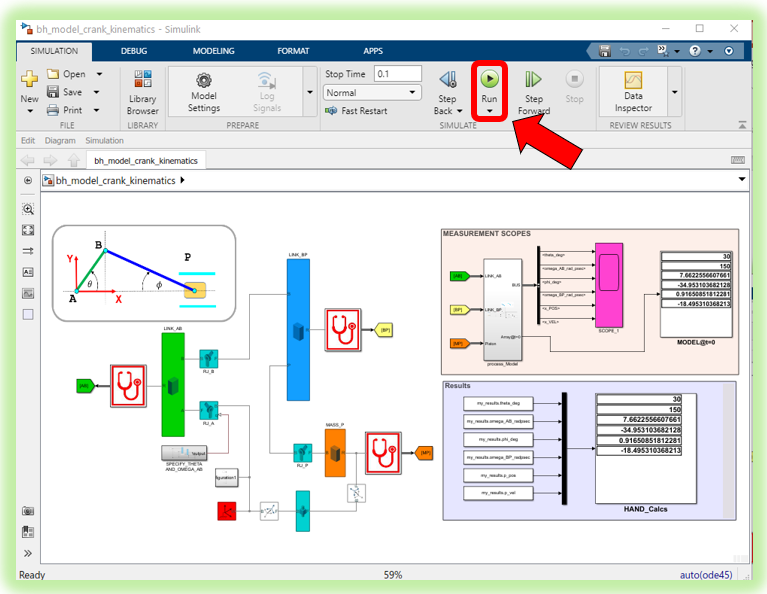

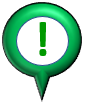  **So what happened ?**

- At time $t=0\;\textrm{seconds}$, this Simulink model of the Slider Crank mechanism, was configured to be in the SAME identical pose as the one that we just did the Velocity analysis on.

- We then ran the simulation for $0\ldotp 1$ seconds.  

- An animation of the meachism was also produced by the simulation.

- During this whole time, the angular velocity of the GREEN link was constant at $\omega_{\textrm{AB}} =150\;\frac{\textrm{rad}}{\sec }$

 **Explore the Simulink model simulation results**

- Explore(double click on it) the PINK SCOPE block and inspect the time series of the various angles and positions .

- When you zoom in around the $t=0\;\textrm{seconds}$ region in the PINK SCOPE, do you see values for $v_P$ and $\omega_{\textrm{BP}}$ that are similar to your hand calculations ?